# Human Activity Classification Using Deep Learning

This is a supervised learning example.

Human activity sensor data contains observations derived from sensor measurements taken from smartphones worn by people while doing six different activities: Walking, Sitting, Laying, Standing, Walking Upstairs, and Walking Downstairs. 

The goal of this example is to build a model that can automatically identify the activity type given the sensor measurements. **In this supervised learning example, we will work with labeled data and ****raw**** data. **

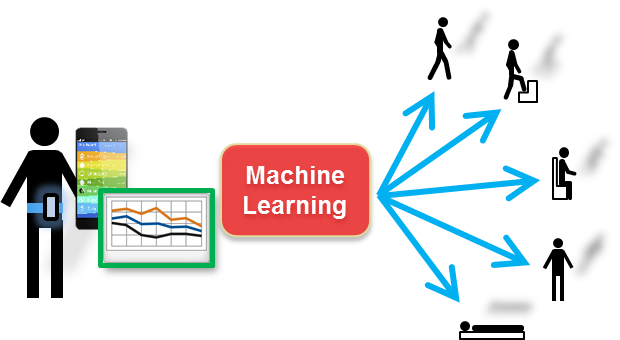

clear;

## Preprocess data

In the previous exercise, we modified the original data and calculated features.

Let's re-load the raw train and test data sets (`rawDataTrain` and `rawDataTest` respectively) and create a table for each set. 

load('rawSensorData_train.mat')
rawDataTrain = table(...
     total_acc_x, total_acc_y, total_acc_z, ...
     body_gyro_x, body_gyro_y, body_gyro_z);

load('rawSensorData_test.mat')
rawDataTest = table(...
    total_acc_x, total_acc_y, total_acc_z, ...
    body_gyro_x, body_gyro_y, body_gyro_z);

Both variables are organised in the same way: the columns represent the individual sensors, and the rows the activities.

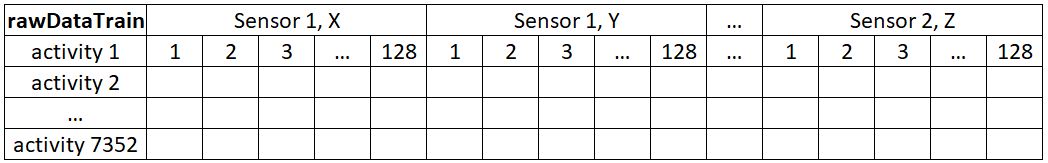

Deep learning can often perform well on raw data, so extracting the features is unnecessarily. However, often "organizing" (or "restructuring") the data can be very beneficial. For this reason, we will organize our data by sensors for the individual activities. This means, we will group all sensors together for each temporal frame (e.g. each 2.5 s frame (=128 measurements) should have all six sensors).  The result is a multidimensional array where each dimension contains the data for that specific time frame (activity). Therefore, we use a helper function (`groupByActivity`) which can be found in *Additional Files*.

numSig_train = size(rawDataTrain,1);
numSig_test = size(rawDataTest,1);

[train_groups, test_groups] = groupByActivity(rawDataTrain, numSig_train, ...
rawDataTest, numSig_test);

train_groups = pagetranspose(train_groups);
test_groups = pagetranspose(test_groups);

Now, the sensors are the columns of each dimension within the array, so each dimension (representing an activity) has 6 columns.

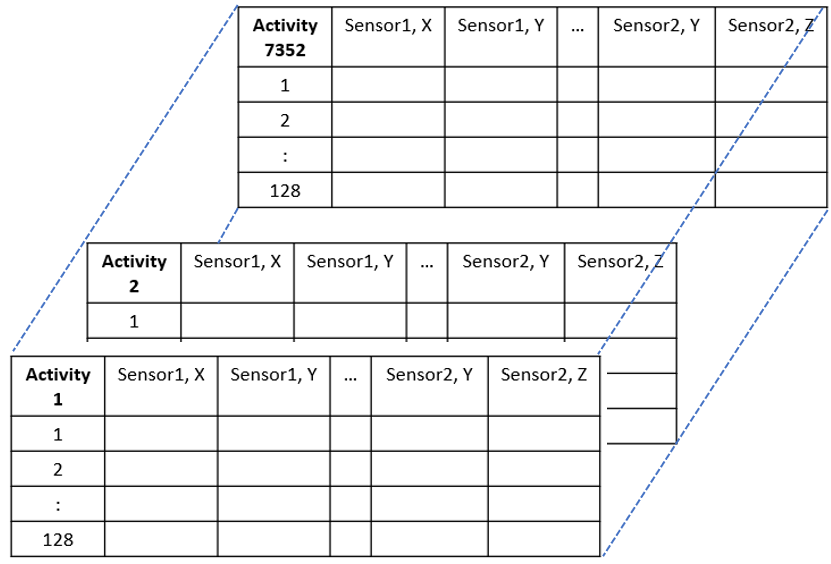

disp(train_groups(:,:,1))

We will be using the Deep Network Designer App to design and train our neural network. The app requires the input data to come from a [datastore](https://uk.mathworks.com/help/matlab/datastore.html), which is a repository for collections of data that are too large to fit in memory. There are different [types of datastores](https://uk.mathworks.com/help/matlab/import_export/select-datastore-for-file-format-or-application.html), in our case, we will be working with [arrayDatastore](https://uk.mathworks.com/help/matlab/ref/matlab.io.datastore.arraydatastore.html).

Our training data consists of different data types (`train_groups` is double and `trainActivity` is categorical). Let's create 2 datastores and combine them.

inDS_train = arrayDatastore(train_groups, IterationDimension=3, OutputType="cell");
outDS_train = arrayDatastore(trainActivity, IterationDimension=1, OutputType="cell");
fullDS_train = combine(inDS_train, outDS_train);

Since we will not be using the `testActivity` variable, we create only one datastore for the test data.

fullDS_test = arrayDatastore(test_groups, IterationDimension=3, OutputType="cell");

## Train the model

LSTM (Long Short-Term Memory) networks can learn long-term dependencies between time steps of sequence data. This example uses the bidirectional LSTM layer [`bilstmLayer`](https://uk.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.bilstmlayer.html), as it looks at the sequence in both forward and backward directions.

**Create LSTM network with Deep Network Designer**

The [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html) (DND) provides a graphical interface for designing and training a neural network.

To open the DND app go to the **APPS** tab, under **Machine Learning and Deep Learning**, click the  icon. Alternatively, you can open the app from the command line

**Step 1: Choose network architecture**

On opening the DND, choose *Blank Network*. 

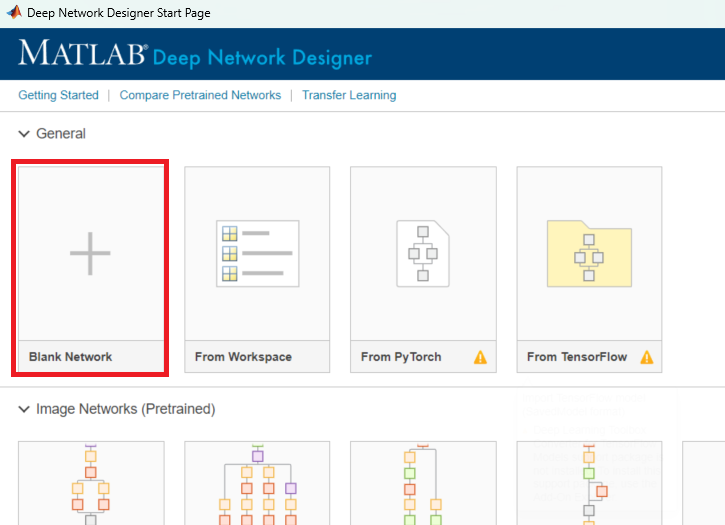

**Step 2: Create the network from scratch**

In the *Designer* tab, create the architecture below by dragging and dropping required layers and setting the required values.

Because we have 6 input signals, specify the input size to be sequences of size 6. Specify a bidirectional LSTM layer with an output size of 128 (default) and output the last element of the sequence for classification. This command instructs the bidirectional LSTM layer to map the input time series into 128 features and then prepares the output for the fully connected layer. Finally, specify 6 classes by including a fully connected layer of size 6, followed by a softmax layer and a classification layer.

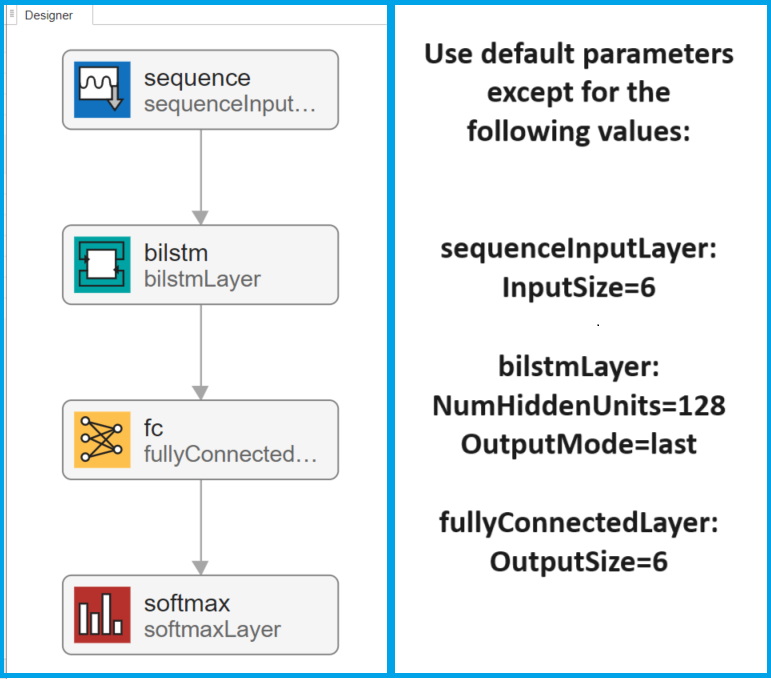

Once we create the network, we can Analyze it to check for errors or warnings. Once satisfied with the network, we can Export the network for training. Note that the Deep Network Designer can export the network and generate code that can be used to create the network.

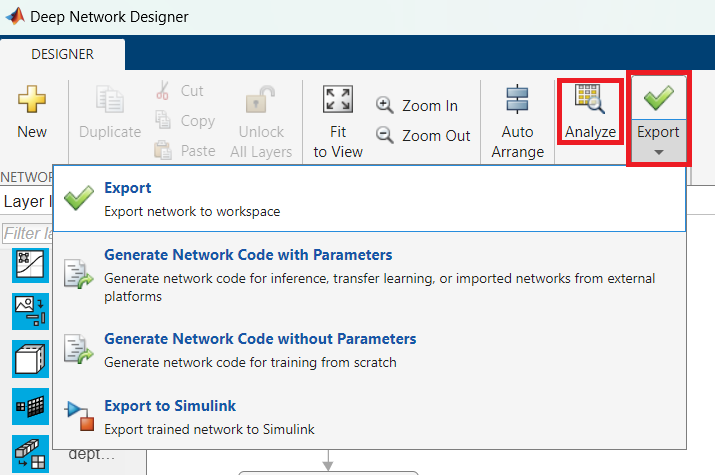

**Step 3: Import the training data**

In the section on preprocessing data, we looked at how to import the train and test data sets. We will use the train dataset to train the designed neural network.

Note: To keep this example simple, we are not using a validation data set. However, to improve the generalization capability of the network (and to avoid overfitting), we strongly recommend to use a validation data set. You can use the command [cvpartition](https://uk.mathworks.com/help/stats/cvpartition.html) to split the original training data set into 2 subsets (one for training and one for validation).

**Step 4: Set Training Options**

We now set the training options for this network, and select the following options (hyperparameters):

- Solver: 'adam'

- MiniBatchSize: 128

- InitialLearnRate: 0.03

- MaxEpochs: 20

- LearnRateSchedule: 'piecewise'

- LearnRateDropFactor: 0.2

- LearnRateDropPeriod: 5

options = trainingOptions('adam', ...
     MaxEpochs = 20, ...
     InitialLearnRate=0.03,...
     MiniBatchSize=128, ...
     LearnRateSchedule= 'piecewise', ...
     LearnRateDropFactor=0.2, ...
     LearnRateDropPeriod=5, ...
     Plots = 'training-progress', ... 
     Metrics='accuracy', ...
     Verbose = false);

**Step 5: Train the network**

net = trainnet(fullDS_train, net_1, "crossentropy", options)

Run the above command to train the network. With a GPU, the training should take approx. 1.5 minutes. Your training plot should look similar to this:

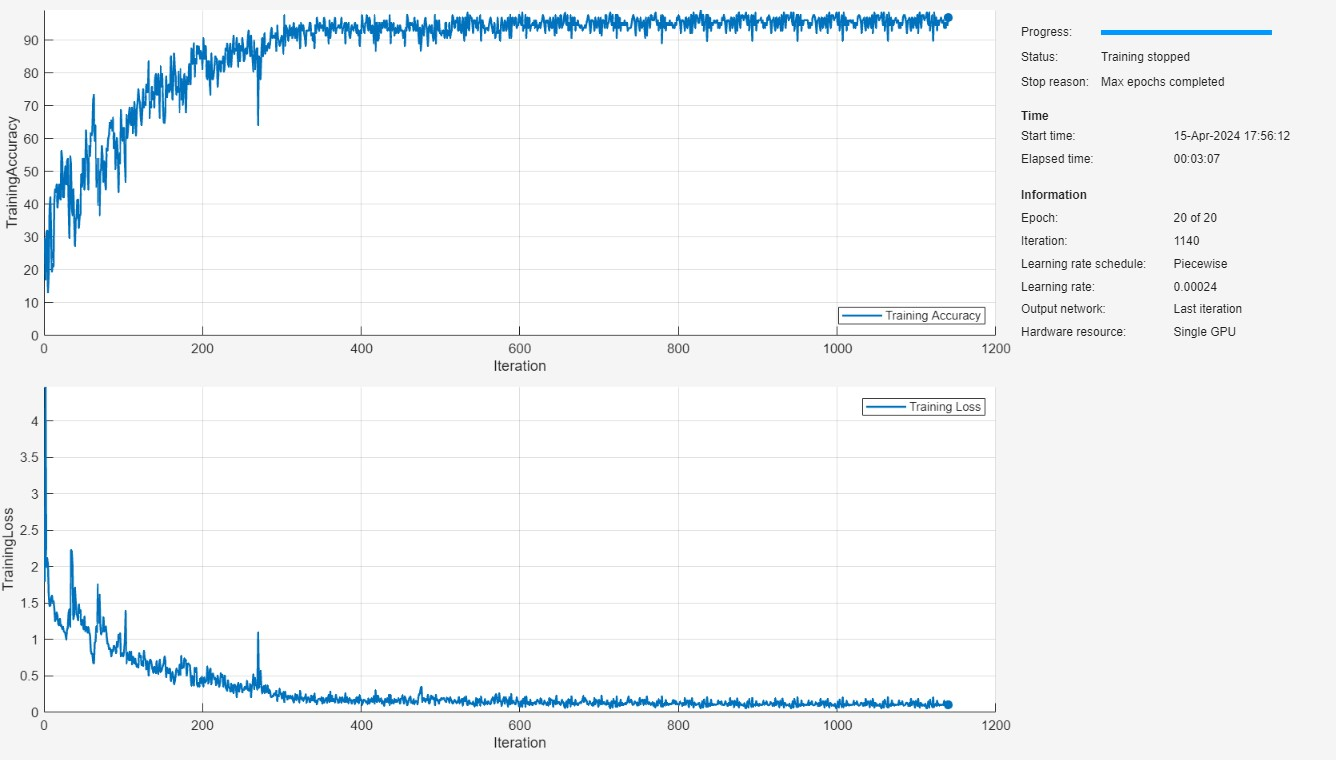

**Step 5: Hyperparameter tuning**

Note: You can use the [Experiment Manager app](https://uk.mathworks.com/help/deeplearning/ref/experimentmanager-app.html) to tune the hyperparameters (slightly more advanced). You could also generate code, so you don't have to do it manually every time. And you can use the trained model in Simulink.

## Evaluate model

Now, you can evaluate it's accuracy on unseen data (`fullDS_test`).

Since we do have the labels of the test data, we ca`n compare the predictions with the actual labels and calculate the test accuracy.

classNames = unique(trainActivity);

y_pred = minibatchpredict(net,fullDS_test);
y_pred = scores2label(y_pred,classNames);

accuracy_test = sum(y_pred == testActivity)/numel(testActivity)*100

accuracy_test =           83.3729216152019


 We can also plot the [confusion chart](https://uk.mathworks.com/help/stats/confusionchart.html) to visualize the results and to see where the network got wrong.

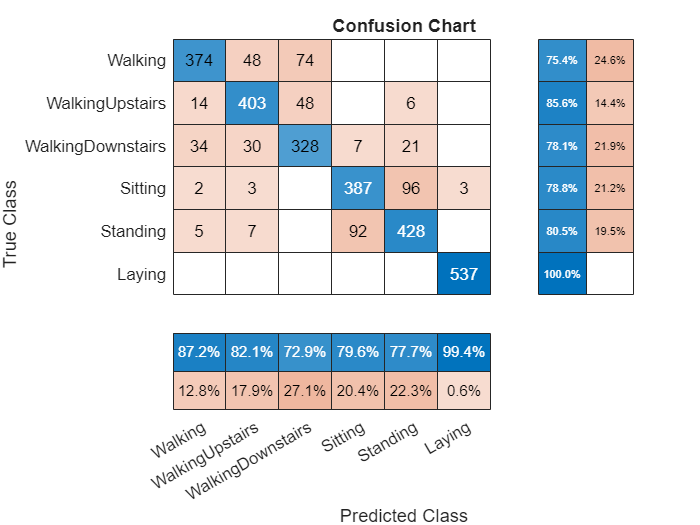

figure
ccLSTM = confusionchart(testActivity,y_pred);
ccLSTM.Title = 'Confusion Chart';
ccLSTM.ColumnSummary = 'column-normalized';
ccLSTM.RowSummary = 'row-normalized';

As we can see, the network struggles mostly with the walking activities (walking, walking upstairs, walking downstairs). This might indicate that measurements from other sensors are required.

## Summary and next steps

In this example we built a deep learning model to classify human activity data which was acquired from a mobile phone. We used raw data, trained a basic model, and evaluated its performance on unseen data.

Clearly we haven’t satisfactorily solved this problem, with the highest test accuracy still around 80%.

Here are some additional steps you could try to improve the test accuracy: 

- More sensor data: Measurements from other data might make it easier for the model to distinguish between the different walking activities.

- Balancing the classes: You might have noticed that the number of observations in each class is different (laying has the most observations, walking downstairs the least). Use techniques such as oversampling or undersampling to balance the classes.

- Improve network architecture: In this example, we used an LSTM-model. By using an alternative model (e.g. "deeper" model with multiple LSTM-layers) the accuracy might also be improved. However, this will most probably require more computational power.

- Hyperparameter tuning:  You can use the [Experiment Manager App](https://www.mathworks.com/help/deeplearning/ug/exp-mgr-classification-example.html) to keep track of all your hyperparameters. Alternatively, you can perform Bayesian Optimization [within the Experiment Manager](https://www.mathworks.com/help/deeplearning/ug/experiment-using-bayesian-optimization.html) or [programmatically](https://www.mathworks.com/help/deeplearning/ug/deep-learning-using-bayesian-optimization.html#d123e28534) to find the best hyperparameters.

*Copyright 2025, The MathWorks, Inc.*